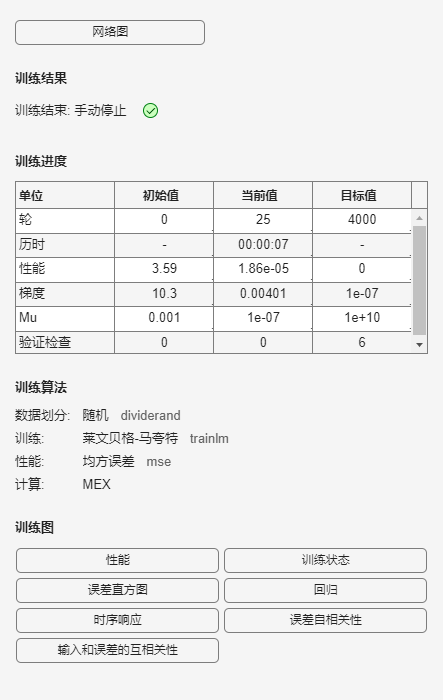

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Train();
% 根据需要选取原始数据
Sys_input(:,1) = Data_matrix(:,1);
Sys_input(:,2) = Data_matrix(:,2);
Sys_output(:,1) = Data_matrix(:,end-1);
Sys_output(:,2) = Data_matrix(:,end);
% 转换为细胞数组（每个时间步为2×1列向量）
Sys_input = num2cell(Sys_input', 1);  % 转为1×N细胞数组
Sys_output = num2cell(Sys_output', 1);

% 创建时间延迟网络
M = 8;
hiddenSizes = [32, 16];

inputDelays = 1:M;
net = timedelaynet(inputDelays, hiddenSizes);

% 准备训练数据
[Xs, Xi, Ai, Ts] = preparets(net, Sys_input, Sys_output);

% 配置训练选项
net.trainFcn = 'trainlm';       % 使用Levenberg-Marquardt算法
net.trainParam.epochs = 4000;   % 最大迭代次数
net.trainParam.max_fail = 6;    % 验证失败次数（类似ValidationPatience）

% 训练网络
model = train(net, Xs, Ts, Xi, Ai);

% 预测输出
AA={};
Y = model(Xs, Xi, AA);

% 转换为数值矩阵并可视化
DPD_output_m = cell2mat(Y);

DPD_output = DPD_output_m(1,:)+1j*DPD_output_m(2,:);
DPD_output = DPD_output.';
nmse = NMSE_dB(Data_matrix(M+1:end,end-1)+1j*Data_matrix(M+1:end,end), DPD_output);
fprintf('模型的拟合精度NMSE为 %f dB\n', nmse);

模型的拟合精度NMSE为 -44.483833 dB
